E 9.1

% E9.1
clear all
s = tf('s');

Ls = 3*(1+5*s)/(s*(4+s)*(1+2*s+2*s^2))

Ls =
 
            15 s + 3
  ----------------------------
  2 s^4 + 10 s^3 + 9 s^2 + 4 s
 
연속시간 전달 함수입니다.
모델 속성


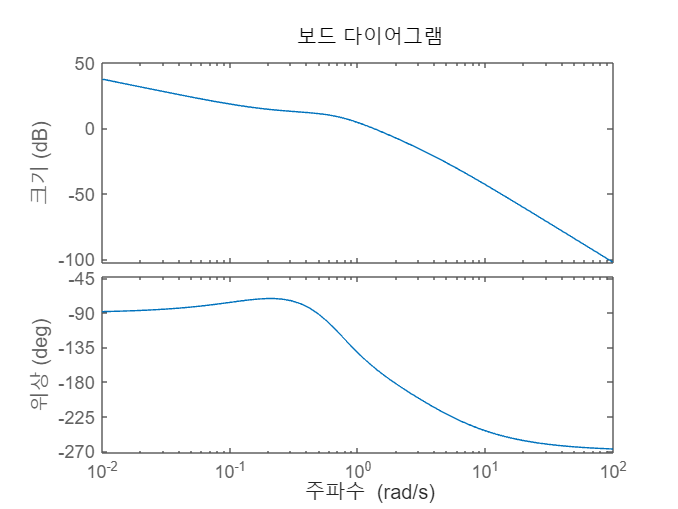

sys = Ls;
bode(sys);

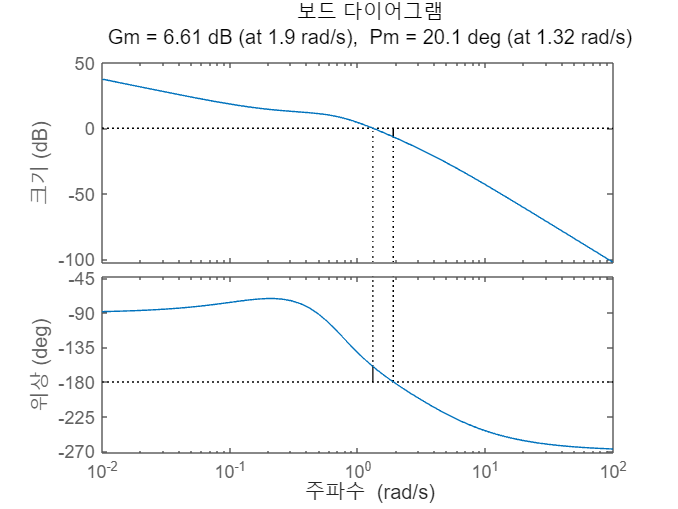

margin(sys);

[Gm, Pm] = margin(sys);
Gm = mag2db(Gm);
Pm;
fprintf("G.M. = %.2f[dB]\nP.M. = %.1f[°]", [Gm, Pm])

G.M. = 6.61[dB]
P.M. = 20.1[°]

E 9.2

% E9.2
clear all
s = tf('s');

K = 4;
% 문제상에는 Ls = K*(1+s/20)/(s*(1+s/8)*(1+s+10)) 로 되어있지만,
% 주어진 교차주파수와 위상여유를 보았을 때 Ls = K*(1+s/20)/(s*(1+s/8)*(1+s+10))로
% 하는것이 맞다.
Ls = K*(1+s/20)/(s*(1+s/8)*(1+s/10))

Ls =
 
        320 s + 6400
  -------------------------
  20 s^3 + 360 s^2 + 1600 s
 
연속시간 전달 함수입니다.
모델 속성


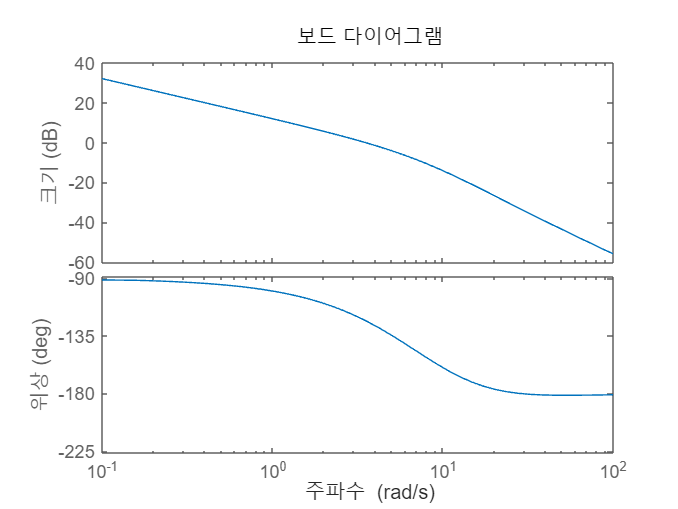

sys = Ls;
bode(sys);

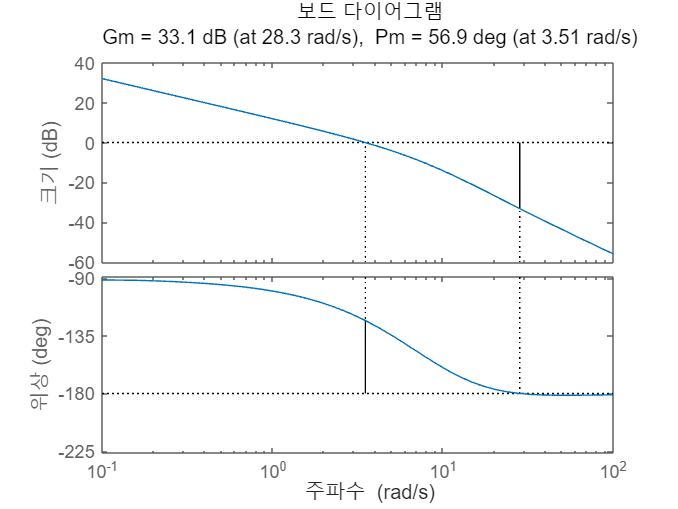

margin(sys);

[Gm, Pm, Wcg, Wcp] = margin(sys);
Gm = mag2db(Gm);
Pm;
fprintf("P.M. = %.1f[°]\n", Pm)

P.M. = 56.9[°]


fprintf("Wcp(위상여유의 교차주파수) = %.2f[rad/s]\n", Wcp)

Wcp(위상여유의 교차주파수) = 3.51[rad/s]


E 9.7

% E9.7
clear all
syms s K

% Ls의 pole을 구하는 과정.
Ls = K/(s-5);
[num, den] = numden(Ls);
eqn = den == 0;
s = solve(eqn,s)    % s = 5 (Ls의 양수부 pole은 1개이다.)

$$s = 5$$

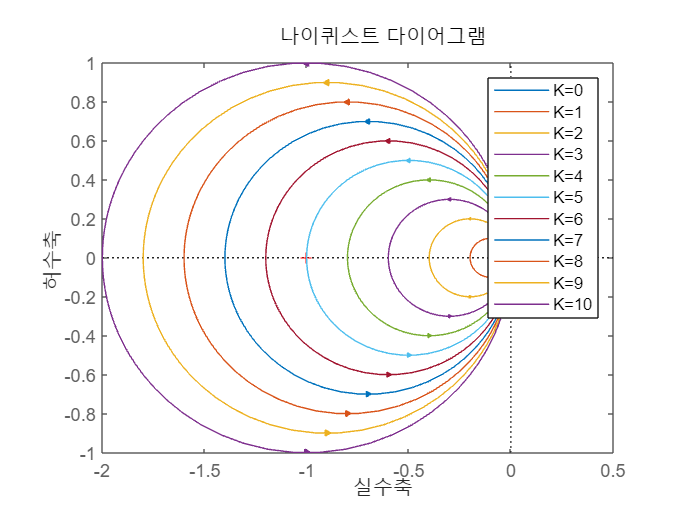


s = tf('s');

sys_leg1 = [];
for K = 0:10
    Ls = K/(s-5);
    nyquist(Ls);
    K1 = string(K);
    sys_leg = strcat('K=',K1);
    sys_leg1 = cat(1,sys_leg1,sys_leg);
    hold on
end
legend(sys_leg1);
hold off

% K=5 일 때는 nyquist 선도가 (-1,0)을 지나며,
% K>5 일 때는 nyquist 선도가 (-1,0)을 반시계 방향으로 1번 둘러싸고,
% K<5 일 때는 nyquist 선도가 (-1,0)을 0번 둘러싼다.
% 
% Ls의 양수부 pole이 1개이므로, 시스템이 안정적이기 위해서는 
% nyquist 선도가 (-1,0)을 반시계 방향으로1번 둘러싸야 한다.
% 따라서 K>5 일 때 시스템은 안정하다

P 9.2

% P9.2

% (a)
clear all
syms s K
% Ls의 pole을 구하는 과정.
Ls = K/(s*(s^2+2*s+5));
[num, den] = numden(Ls);
eqn = den == 0;
s = solve(eqn,s)    % s = 0, -1±2i (Ls의 양수부 pole은 0개이다.)

$$s = \left(\begin{array}{c} 0\\ -1-2\,\mathrm{i}\\ -1+2\,\mathrm{i} \end{array}\right)$$

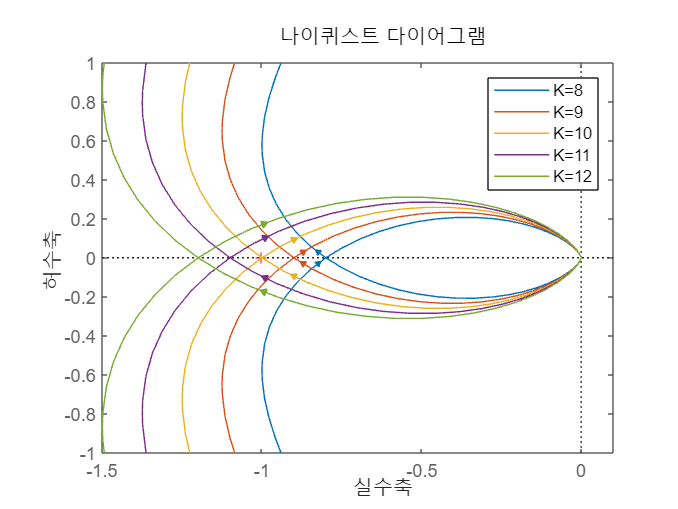


s = tf('s');
sys_leg1 = [];
for K = 8:12
    Ls = K/(s*(s^2+2*s+5));
    nyquist(Ls);
    K1 = string(K);
    sys_leg = strcat('K=',K1);
    sys_leg1 = cat(1,sys_leg1,sys_leg);
    hold on
end
axis([-1.5 0.1 -1 1])
legend(sys_leg1);
hold off

% K=10 일 때는 nyquist 선도가 (-1,0)을 지나며,
% K>10 일 때는 nyquist 선도가 (-1,0)을 시계 방향으로 1번 이상 둘러싸고,
% K<10 일 때는 nyquist 선도가 (-1,0)을 0번 둘러싼다.
% 
% Ls의 양수부 pole이 0개이므로, 시스템이 안정적이기 위해서는 
% nyquist 선도가 (-1,0)을 둘러싸면 안 된다.
% 따라서 K<10 일 때 시스템은 안정하다.

% (b)
clear all
syms s K
% Ls의 pole을 구하는 과정.
Ls = K*(s+2)/(s^2*(s+5));
[num, den] = numden(Ls);
eqn = den == 0;
s = solve(eqn,s)    % s = 0, -5 (Ls의 양수부 pole은 0개이다.)

$$s = \left(\begin{array}{c} -5\\ 0\\ 0 \end{array}\right)$$

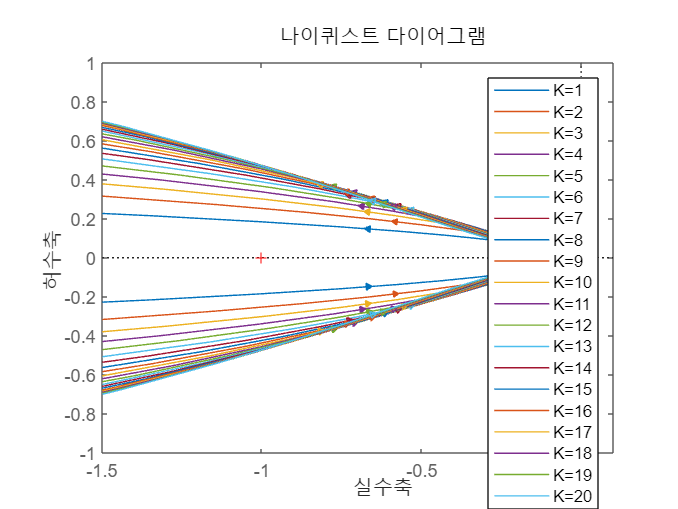


s = tf('s');
sys_leg1 = [];
for K = 1:20
    Ls = K*(s+2)/(s^2*(s+5));
    nyquist(Ls);
    K1 = string(K);
    sys_leg = strcat('K=',K1);
    sys_leg1 = cat(1,sys_leg1,sys_leg);
    hold on
end
axis([-1.5 0.1 -1 1])
legend(sys_leg1);
hold off

% 선도가 실수축 음의 방향으로 발산하긴 하지만,
% Ls의 양수부 pole이 0개 일 때 *시계방향*으로 감싸게 된다는 전제조건이 있다.
% 만약 nyquist 선도가 (-1,0)을 감싸게 된다 하더라도 시계방향이 아니기 때문에
% K 값에 관계없이 nyquist 선도는 (-1,0)을 감싸거나 지나치지 않는다.
% 따라서 K값에 관계없이 시스템은 안정하다.

P 9.5

% P9.5
clear all
syms s K tau_t tau_e tau_m Rs e_ss w

tau_t = 1.5;
tau_e = 4;
tau_m = 0.6;
Gc = 1/(tau_t*s+1);
G = K/(tau_e*s+1);
H = 1/(tau_m*s+1);
Ls = Gc*G*H             % Ls = Gc*G*H 이라 하자.

$$Ls = \frac{K}{\left(4\,s+1\right)\,\left(\frac{3\,s}{2}+1\right)\,\left(\frac{3\,s}{5}+1\right)}$$

Ts = simplify(Gc*G/(1+Ls))

$$Ts = \frac{2\,K\,\left(3\,s+5\right)}{36\,s^{3}+93\,s^{2}+61\,s+10\,K+10}$$

% (a)
eqn = e_ss == Rs - H*Gc*G*e_ss

$$eqn = e_{\mathrm{ss}}=\mathrm{Rs}-\frac{K\,e_{\mathrm{ss}}}{\left(4\,s+1\right)\,\left(\frac{3\,s}{2}+1\right)\,\left(\frac{3\,s}{5}+1\right)}$$

e_ss = simplify(limit(solve(eqn,e_ss),s,0))

$$e\_ss = \frac{\mathrm{Rs}}{K+1}$$

e_ss < 0.2*Rs

$$ans = \frac{\mathrm{Rs}}{K+1}<\frac{\mathrm{Rs}}{5}$$

% 위 부등식을 Rs>0, K>-1 이라고 가정하면, K>4 이다.

% (b)
[n, d] = numden(Ls);
eqn = d == 0;
s = solve(eqn,s)    % s = -2.5, -1, -0.333 (Ls의 양수부 pole은 0개이다.)

$$s = \left(\begin{array}{c} -\frac{5}{3}\\ -\frac{2}{3}\\ -\frac{1}{4} \end{array}\right)$$

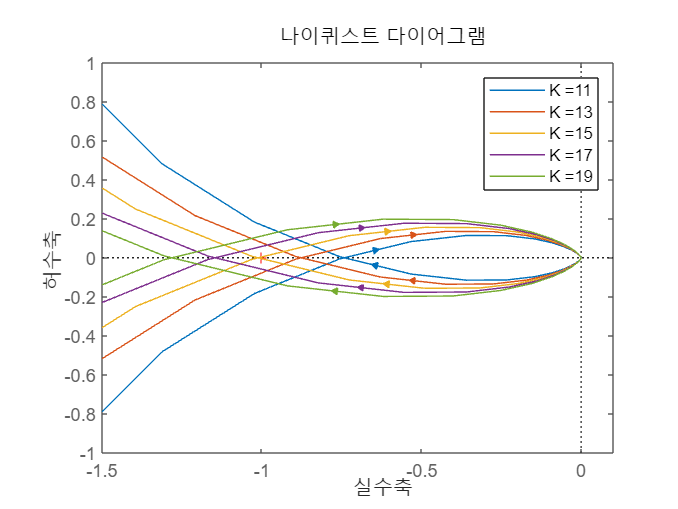


den = sym2poly(d);
sys_leg = [];
for K1 = 11:2:19
    num = sym2poly(subs(n,K,K1));
    sys_Ls = tf(num, den);
    nyquist(sys_Ls);

    K2 = string(K1);
    sys_leg1 = strcat('K = ',K2);
    sys_leg = cat(1,sys_leg,sys_leg1);
    hold on;
end
axis([-1.5 0.1 -1 1])
legend(sys_leg);
hold off


% (-1, 0)을 지나는 K 값을 구하는 함수 start
syms s
assume(w,'Real');
[num_T, den_T] = numden(subs(Ts,s,1i*w));
w_T = solve(real(den_T) == 0,w);

K_discri = double(solve(subs(-93*w^2+10*K+10,w,w_T(3)),K))

K_discri = 14.7583

% (-1, 0)을 지나는 K 값을 구하는 함수 end

% K=14.7583 일 때는 nyquist 선도가 (-1,0)을 지나며,
% -1<K<14.7583 일 때는 nyquist 선도가 (-1,0)을 0번 둘러싸며,
% K>14.7583 일 때는 nyquist 선도가 (-1,0)을 시계 방향으로 2번 둘러싼다.
% 
% Ls의 양수부 pole이 0개이므로, 시스템이 안정적이기 위해서는
% nyquist 선도가 (-1,0)을 둘러싸면 안 된다.
% 따라서 시스템이 안정하며, 오차율이 20% 미만이기 위해서는
% 4<K<14.7583 이어야 한다.

% (c)
% 만약 K = 4 라면(오차율이 20%라면)
Ls = subs(Ls,K,4)   % Ls 의 여유를 구했을 때

$$Ls = \frac{4}{\left(4\,s+1\right)\,\left(\frac{3\,s}{2}+1\right)\,\left(\frac{3\,s}{5}+1\right)}$$

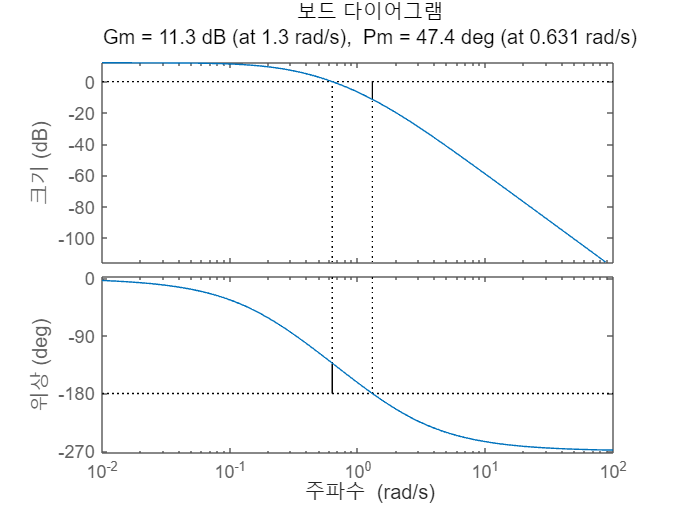

[n, d] = numden(Ls);
num = sym2poly(n);
den = sym2poly(d);
sys_Ls = tf(num, den);
margin(sys_Ls);

[Gm, Pm] = margin(sys_Ls)

Gm = 3.6896

Pm = 47.4174


Ts = subs(Ts,K,4)   % 궤환시스템(Ts)의 여유를 구했을 때

$$Ts = \frac{8\,\left(3\,s+5\right)}{36\,s^{3}+93\,s^{2}+61\,s+50}$$

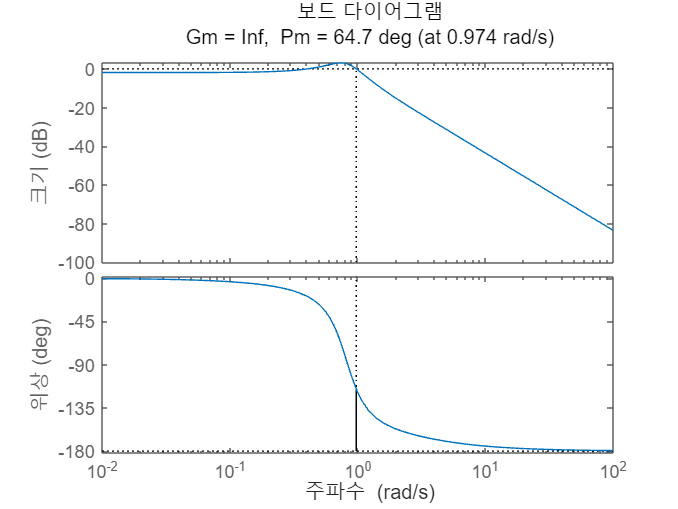

[n, d] = numden(Ts);
num = sym2poly(n);
den = sym2poly(d);
sys_Ts = tf(num, den);
margin(sys_Ts);

[Gm, Pm] = margin(sys_Ts)

Gm = Inf

Pm = 64.6640